# Digital Communication Modulations

## Niusha Mirhakimi

close all;
clear;
clc;

## Part 1

By keeping the mean of the random variables constant and varying the standard deviation, three sets of normally distributed numbers are generated. The histogram of these sets are plotted, each with 100 bars.

mu = 0;
rng('shuffle');
N = 1000000;
size_ = [N, 1];
bars_num = 100

bars_num = 100

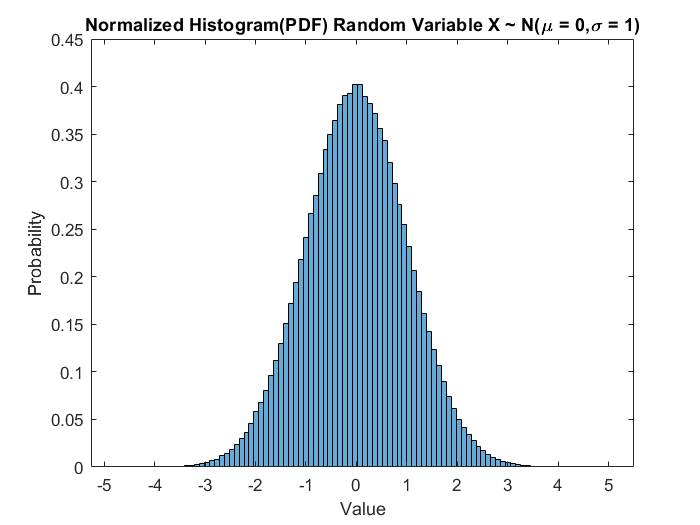

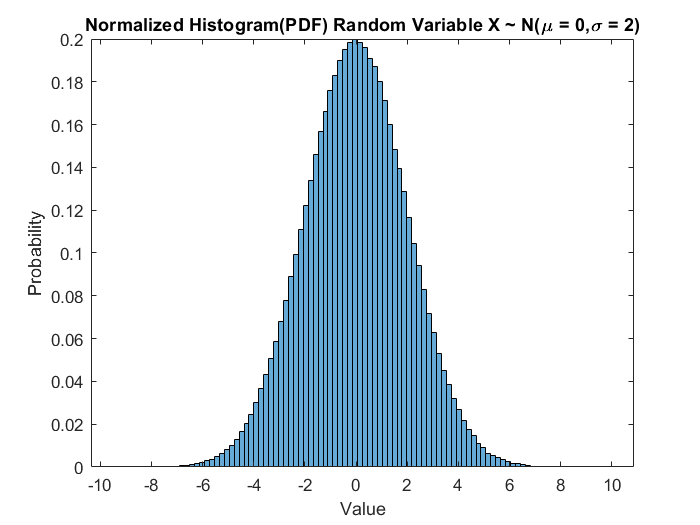

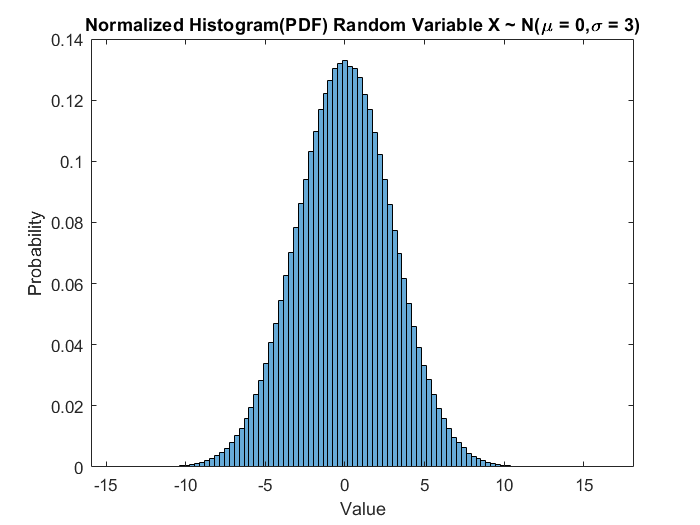

for sigma = [1 2 3]
    nums = normrnd(mu, sigma, size_);
    figure;
    histogram(nums, bars_num, 'Normalization', 'pdf')
    xlabel("Value");
    ylabel("Probability");
    title("Normalized Histogram(PDF) Random Variable X ~ N(\mu = "...
        + mu + ",\sigma = " + sigma + ")")
end

## Part 2

It is clear that the expected value of random variable X equals 5. Now if we denote the standard Gaussian random varibale by N for random variable Y we have:


$$E\left\lbrace Y\right\rbrace =E\left\lbrace N+5\right\rbrace =E\left\lbrace N\right\rbrace +5$$


Since the mean of a standard Gaussian random variable equals 0:


$$E\left\lbrace Y\right\rbrace =0+5=5$$


The observations in the code also certify that the theoretical analysis is valid.

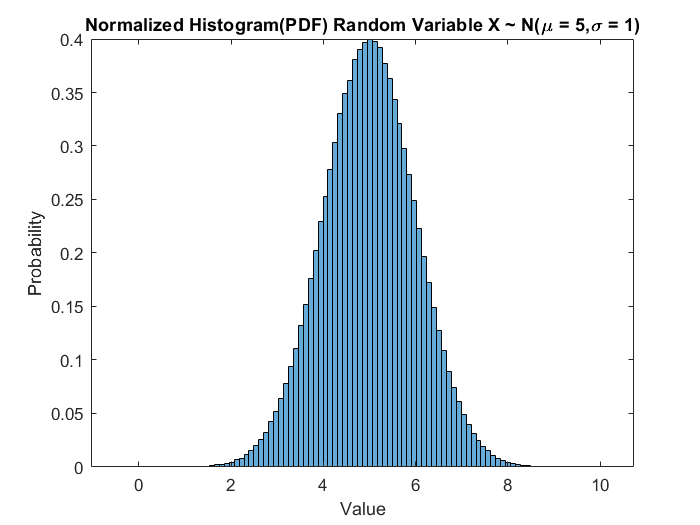

sigma = 1;
X = normrnd(mu + 5, sigma, size_);
figure;
histogram(X, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Random Variable X ~ N(\mu = "...
    + (mu + 5) + ",\sigma = " + sigma + ")")

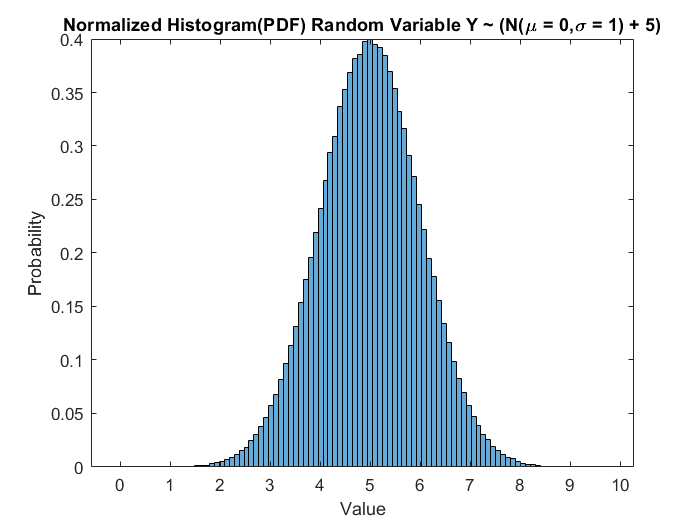

Y = normrnd(mu, sigma, size_) + 5;
histogram(Y, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Random Variable Y ~ (N(\mu = "...
    + mu + ",\sigma = " + sigma + ") + 5)")

"Mean of X: " + mean(X)

ans = "Mean of X: 4.9998"

"Mean of Y: " + mean(Y)

ans = "Mean of Y: 4.9976"

## Part 3

For generating random numbers in set of {-1, 1} the function randsrc is used. The the noise is added to the original signal and then the histogram of the resulting signal is plotted.

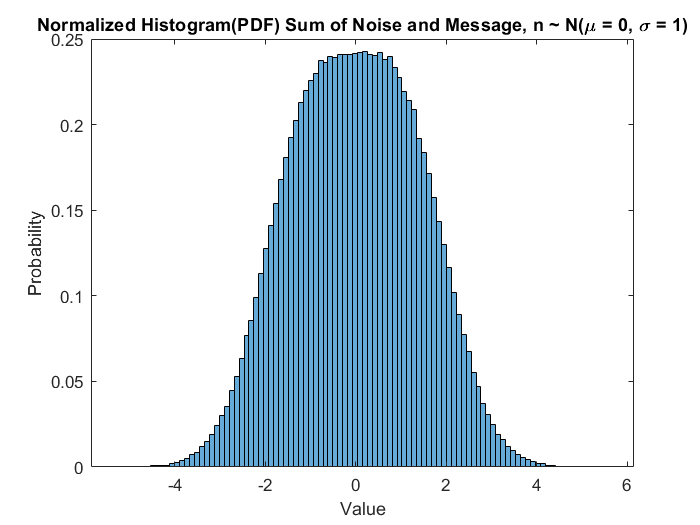

p1 = 0.5;
p2 = 0.5;
signal = randsrc(N, 1, [1, -1; p1, p2]);
noise = normrnd(mu, sigma, size_);
recieved_signal = signal + noise;
figure;
histogram(recieved_signal, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Sum of Noise and Message, n ~ N(\mu = "...
    + mu + ", \sigma = " + sigma + ")")

In the above plot, the two peaks are not much distinguishable, but if we decrease the variance of the noise, this problem will also vanish.

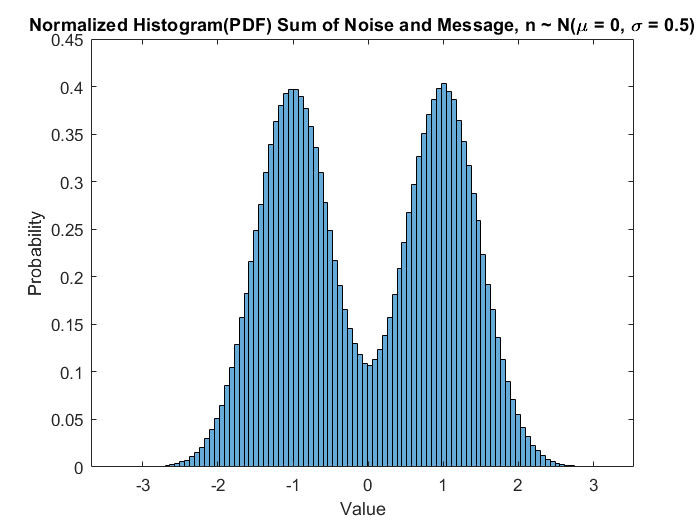

sigma = 0.5;
noise = normrnd(mu, sigma, size_);
recieved_signal = signal + noise;
figure;
histogram(recieved_signal, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Sum of Noise and Message, n ~ N(\mu = "...
    + mu + ", \sigma = " + sigma + ")")

## Part 4

If we change the values of p1 and p2 as the question asked, the output is more probable to get values near -1. By observing the histogram of the output this phenomena can be clearly seen.

The decison criterion must be determined as follows:


$$\begin{array}{l}
c=\mathrm{argmax}\left\lbrace \mathrm{Pr}\left\lbrace \mathrm{correct}\;\mathrm{decision}\right\rbrace \right\rbrace =\mathrm{argmin}\left\lbrace \mathrm{Pr}\left\lbrace \mathrm{error}\right\rbrace \right\rbrace \\
=\mathrm{argmin}\left\lbrace \mathrm{Pr}\left\lbrace 1\;\mathrm{recovered}\;|\;-1\;\mathrm{sent}\right\rbrace \times \mathrm{Pr}\left\lbrace -1\;\mathrm{sent}\right\rbrace +\mathrm{Pr}\left\lbrace 0\;\mathrm{recovered}\;|\;1\;\mathrm{sent}\right\rbrace \times \mathrm{Pr}\left\lbrace 1\;\mathrm{sent}\right\rbrace \right\rbrace \;\\
=\mathrm{argmin}\left\lbrace \mathrm{Pr}\left\lbrace \mathrm{message}>c\right\rbrace \times 0\ldotp 7+\mathrm{pr}\left\lbrace \mathrm{message}<c\right\rbrace \times 0\ldotp 3\right\rbrace \\
=\mathrm{argmin}\left\lbrace 0\ldotp 7\left(1-G\left(c-1\right)\right)+0\ldotp 7\;G\left(c+1\right)\right\rbrace 
\end{array}$$


By finding the solution to the above equaion, the optimal criterion can be obtained.

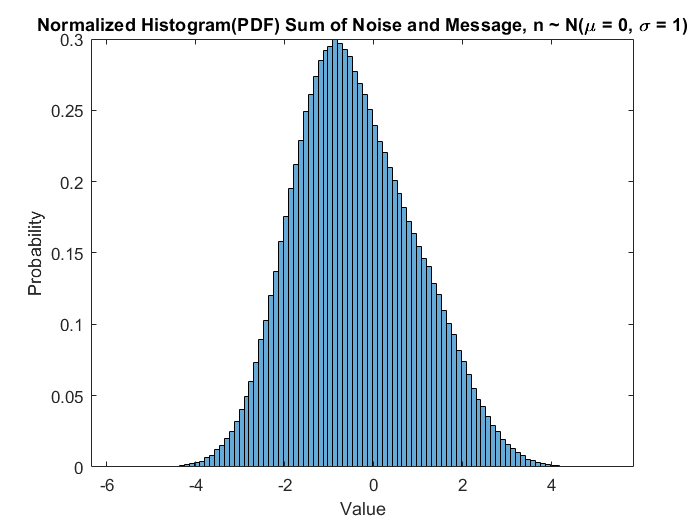

sigma = 1;
mu = 0;
p1 = 0.3;
p2 = 0.7;
signal = randsrc(N, 1, [1, -1; p1, p2]);
noise = normrnd(mu, sigma, size_);
recieved_signal = signal + noise;
figure;
histogram(recieved_signal, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Sum of Noise and Message, n ~ N(\mu = "...
    + mu + ", \sigma = " + sigma + ")")

The same as previous diagram, if we decrease the variance of the noise the differences can be much more clear:

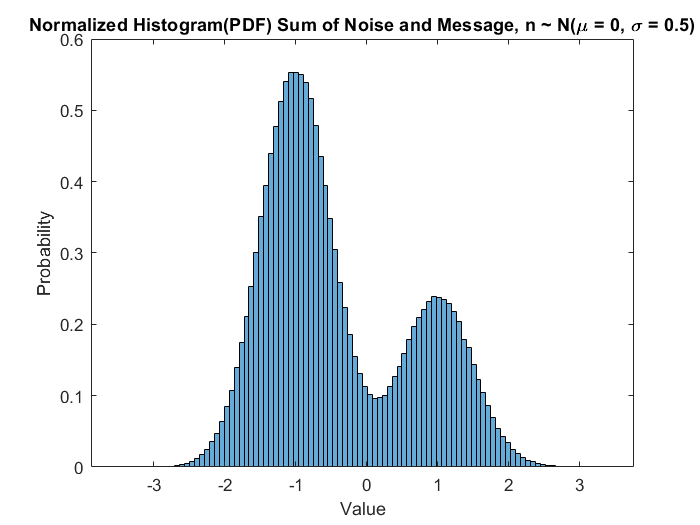

sigma = 0.5;
mu = 0;
p1 = 0.3;
p2 = 0.7;
signal = randsrc(N, 1, [1, -1; p1, p2]);
noise = normrnd(mu, sigma, size_);
recieved_signal = signal + noise;
figure;
histogram(recieved_signal, bars_num, 'Normalization', 'pdf');
xlabel("Value");
ylabel("Probability");
title("Normalized Histogram(PDF) Sum of Noise and Message, n ~ N(\mu = "...
    + mu + ", \sigma = " + sigma + ")")

## Part 5

The power of the transmitted signal equals 1, and if we consider the variance of the noise as its power, then the noise must be devided by the square root of the SNR, or equally the original signal must be multiplied by the square root of the SNR. 

For the given SNRs, random noise is genereated and added with random signals. Then based on the given criterion the output is detected and the error is calculated as the ration of the number of the wrong detections over the total bits transmitted. Finally the figure of the error as a function of SNR is plotted. Also in the same figure Q(SNR) is plotted. It is clear that both theoretical and experimental outputs match, as the two plots are indistinguishable.


$$\begin{array}{l}
p_e =\mathrm{Pr}\left\lbrace 1\mathrm{recieved}\;|-1\;\mathrm{transmitted}\right\rbrace \times \mathrm{Pr}\left\lbrace -1\;\mathrm{transmitted}\right\rbrace +\mathrm{Pr}\left\lbrace -1\;\mathrm{transmitted}\;|\;1\;\mathrm{recieved}\right\rbrace \\
=\mathrm{Pr}\left\lbrace n<\;-1\right\rbrace \times 0\ldotp 5+\mathrm{Pr}\left\lbrace n>1\right\rbrace \times 0\ldotp 5=2\times \;0\ldotp 5\times \;Q\left(\frac{1}{\sigma {\;}_{\mathrm{noise}} }\right)=Q\left(\frac{1}{\sigma_{\mathrm{noise}} }\right)\\
\mathrm{Where}\;\sigma_{\mathrm{noise}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{standard}\;\mathrm{deviation}\;\mathrm{of}\;\mathrm{the}\;\mathrm{noise}\;\mathrm{signal}\ldotp 
\end{array}$$


As stated earlier the variance of the noise equals the energy of it. Also since the message has unit power, the standard deviation of the noise equals the reciprocal of the sqaure root of the SNR. So:


$$p_e =Q\left(\frac{1}{\sigma_{\mathrm{noise}} }\right)=Q\left(\sqrt{{\left(\frac{S}{N}\right)}_R }\right)$$


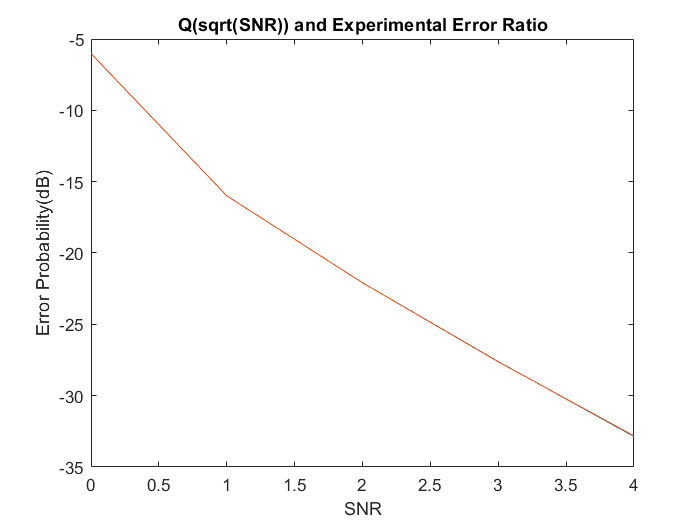

mu = 0;
sigma = 1;
size_ = [5, N];
p1 = 0.5;
p2 = 0.5;
SNR = (0 : 4)';
signal = randsrc(5, N, [1, -1; p1, p2]);
noise = normrnd(mu, sigma, size_);
recieved_signal = signal .* sqrt(SNR) + noise;
output = zeros(size_);
output(recieved_signal > 0) = 1;
output(recieved_signal <= 0) = -1;
error = sum(output ~= signal, 2) / N;
figure;
plot(SNR, 20 * log10(1 - normcdf(sqrt(SNR))))
hold on
plot(SNR, 20 * log10(error))
xlabel("SNR")
ylabel("Error Probability(dB)");
title("Q(sqrt(SNR)) and Experimental Error Ratio")

Since two curves of the above figure are not distinguishable, each of them are alos plotted in another figure individually:

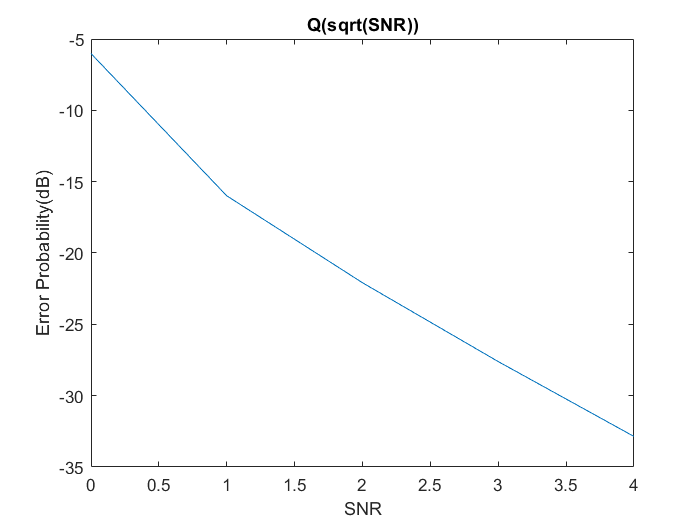

figure;
plot(SNR, 20 * log10(1 - normcdf(sqrt(SNR))))
xlabel("SNR")
ylabel("Error Probability(dB)");
title("Q(sqrt(SNR))")

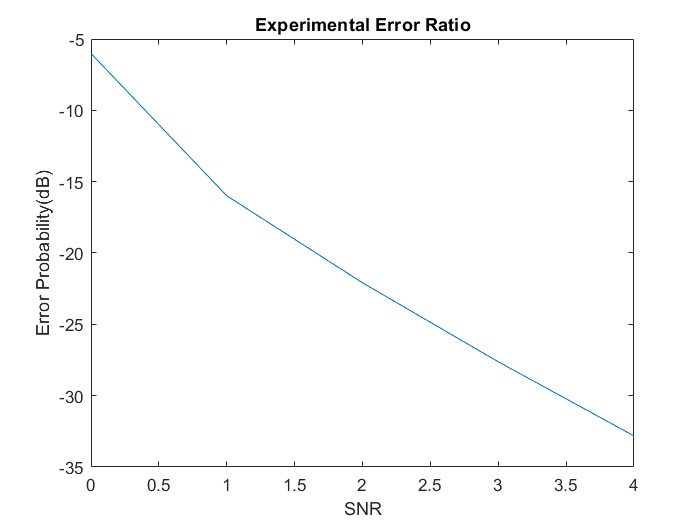

figure;
plot(SNR, 20 * log10(error))
xlabel("SNR")
ylabel("Error Probability(dB)");
title("Experimental Error Ratio")